# Learning to code for classification instead of using ClassificationLearner

#### This code has been heavily taken from the Week 11 Option B assignment answer key. I walked through each step of the code as I transffered it to this file.

06/18/2020

This step is essentially the same as checking boxes to select features in classification learner.

% Select the variables that are not the labels.
predictorNames = traindata.Properties.VariableNames(2:end); %name of predictors (features)
predictors = traindata(:,predictorNames); %data associated with the predictor name

We want to make sure we keep the labels safely so that we can refer back to them when need be.

% Response is the labels, just putting this in a separate variable to match 
% the matlab documentation
response = traindata(:,'labels'); %labels (A pressed or S pressed)

This is the equivalent of selecting a classifier from the drop down menu in classificationLearner. In this case, we have selected Linear SVM.

% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(predictors, ...
    response, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );  % Linear SVM

This step is similar to selecting cross validation when we begin a new session in classificationLearner.

% k-fold cross validation
kval = 5; %Choose number of folds.
cpart = cvpartition(response{:,1},'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);

This step tells us the % accuracy of the classifier we try on our data. This is the same as the number we attain by clicking the train button in classificationLearner.

% Make predictions of the crossfold validation predicted based on the
% traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = 1 - kfoldLoss(partitionedModel);
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 84.26%


We can make a confusion matrix to understand our classification model better.

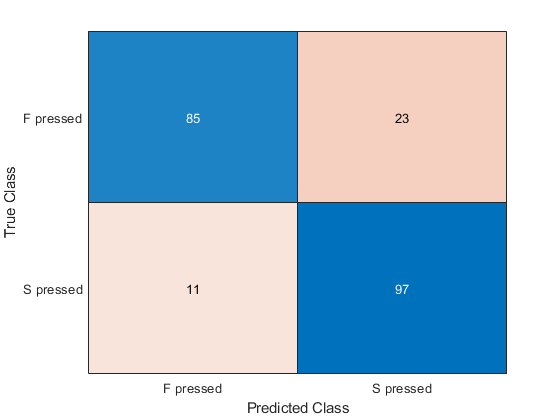

trainconchart = confusionchart(traindata.labels,validationPredictions);

Confusion matrix with percentages instead of #s. 

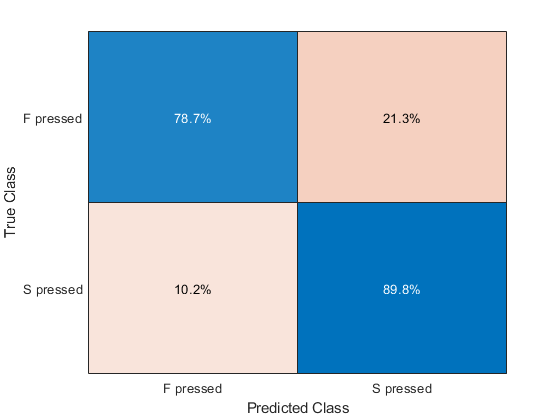

trainconchartNorm = confusionchart(traindata.labels,validationPredictions,'Normalization','row-normalized');